# Unadjusted Asset Backtesting Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 13/07/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

#### **Test Data: **ASSET Log Dif Returns

"DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat"

## **Purpose**

**This file runs a 'classic' backtest where the mean and varaince input to optimizations are ****historical mean and variance.**

#### **Note on file and class structures:**

Here the **benchmark functions** (methods) are stored separately to the **backtesting functions** (methods) as we can later make the benchmark class a subclass to the backtesting class. We can also have the **hrp functions** (methods) as a subclass of the benchmark class as it houses its own specialised functions but is used as a benchmark portfolio optimization. 

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = "DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat";
load(fileName)

M_Ret_TT = M_Ret_TT(2:end,:);
% Find the minimum value and its index in the JIBA3M column
[minValue, minIndex] = min(M_Ret_TT.Cash);

% Get the date corresponding to the minimum value
minDate = M_Ret_TT.Time(minIndex);

2.1 Create ASSETCL plot names (excludes the underscore)

% % rename the variables with underscores instead of spaces
% ASSETCL_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% % remove the 'TR' the variables with underscores instead of spaces
% ASSETCL_PlotNames = strrep(ASSETCL_PlotNames, 'TR', '');

newNames = strrep(M_Ret_TT.Properties.VariableNames, 'TR', '');
M_Ret_TT = renamevars(M_Ret_TT, M_Ret_TT.Properties.VariableNames, newNames);

## 3. Overlapping Rolling Window Backtest

tickersToExtract = {'JALSH_Index', 'Cash','ALB_Index'};
BF_BH_TT = M_Ret_TT(:, tickersToExtract);

M_Ret_TT = removevars(M_Ret_TT, 'JALSH_Index');
Rfr = mean(M_Ret_TT.Cash);

% rename the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(ASSETCL_PlotNames, 'TR', '');

### 3.1 Set Up Storage for Backtest (Full Data Set)

[m,n]=size(M_Ret_TT); % size of full data set
Window = 36;
AssetList = M_Ret_TT.Properties.VariableNames;
% Rfr = mean(M_Ret_TT.JIBA3M_Index);
%###### initialize storage and inputs:

% ### 1. Equally Weighted (EW)###
Overlap_tsEW_Wts0 = eqweight(M_Ret_TT); % [equity, cash, bonds] - balanced fund 60:40 
Overlap_tsEW_Wts = zeros(m,n); 
Overlap_tsEW_PRet = zeros(m,1); % storage for Portfolio Ret
% ### 2. SR Maximizing ###
Overlap_tsSR_Wts = zeros(m,n); % storage for Portfolio Weights
Overlap_tsSR_PRet = zeros(m,1); 
% ### 3. Balanced Fund Buy-Hold ###
Overlap_tsBH_Wts = [0.60,0.05,0.35]; % [equity, cash, bonds] - balanced fund 60:40 
% Overlap-window weights beginning of months
Overlap_tsBH_Wts0 = zeros(m,3);   % for t-th month
% Overlap-window weights end of months
Overlap_tsBH_WtsEnd = zeros(m,3); 
Overlap_tsBH_PRet = zeros(m,1);
% ### 4. HRP ###
Overlap_tsHRP_Wts = zeros(m,n);
Overlap_tsHRP_PRet = zeros(m,1); 
% ### 5. Balanced Fund Constant Mix (CM) ###
Overlap_tsCM_Wts0 = [0.60,0.05,0.35]; % [equity, cash, bonds] - balanced fund 60:40 
Overlap_tsCM_Wts = zeros(m,3); 
Overlap_tsCM_PRet = zeros(m,1); 

Wts_lb = [ 0 0 0 0 0 ]; 
Wts_up = [ 1 1 1 1 0.05];

### 3.2 Set Up Backtest Loop

for t=Window:m-1
%  backtest_object.returns = return_data{1+t-Window:t-1, :};
  
    % Need to calc pr for each window (but type stays the same)
%  [hsfp_mu, hsfp_cov,p] = backtest_moments(backtest_object)
%%%%% need new stats of new window each time %%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 m_t = exp(mean(log(M_Ret_TT{1+t-Window:t-1, :}+1)))-1;

%   m_t = mean(M_Ret_TT{1+t-Window:t-1, :});
  cov_t = cov(M_Ret_TT{1+t-Window:t-1,:});
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

  %%%%% WEIGHTINGS %%%%%%
  % 1. EW
    % initialise wts as equally weighted
    Overlap_tsEW_Wts(t,:) = Overlap_tsEW_Wts0; % Constant Mix (CM)

  % 2. SR
    % initialise wts as equally weighted
%     Overlap_tsSR_Wts(t,:) = maxsr(AssetList, m_t,cov_t, M_Ret_TT.Cash(t));
    Overlap_tsSR_Wts(t,:) = maxsr(AssetList, m_t,cov_t, M_Ret_TT.Cash(t-1,:));

  % 3. Balanced BH 
    % initialise wts as equally weighted
    Overlap_tsBH_Wts0(Window,:) = Overlap_tsBH_Wts; % initial weights
    
  % 4. HRP 
    Overlap_tsHRP_Wts(t,:) = hrpestimate(cov_t)';

  % 5. Balanced CM 
   % 3. Rebalance weighs
    Overlap_tsCM_Wts(t,:) = Overlap_tsCM_Wts0; % Constant Mix (CM)

  %%%%% PORT RETURNS %%%%%%
  % 1. EW
    Overlap_tsEW_PRet(t+1,:) = Overlap_tsEW_Wts(t,:) * transpose(M_Ret_TT{t+1,:});
  % 2. SR
    Overlap_tsSR_PRet(t+1,:) =  Overlap_tsSR_Wts(t,:) * transpose(M_Ret_TT{t+1,:});

  % 3. Balanced BH 
    Overlap_tsBH_PRet(t+1,:) = Overlap_tsBH_Wts0(t,:) * transpose(BF_BH_TT{t+1,:});
    
  % 4. HRP 
    Overlap_tsHRP_PRet(t+1,:) = Overlap_tsHRP_Wts(t,:) * transpose(M_Ret_TT{t+1,:});

  % 5. Balanced CM 
    Overlap_tsCM_PRet(t+1,:) = Overlap_tsCM_Wts(t,:) * transpose(BF_BH_TT{t+1,:});

 %%%%% UPDATE BH %%%%%%%
 % Calc month end weight
 Overlap_tsBH_WtsEnd(t,:) = (BF_BH_TT{t,:}.*Overlap_tsBH_Wts0(t,:))+ Overlap_tsBH_Wts0(t,:);
 % Calc month (i+1) weights
 Overlap_tsBH_Wts0(t+1,:) = Overlap_tsBH_WtsEnd(t,:)/sum(Overlap_tsBH_WtsEnd(t,:));
end

### 3.3 Weight surfaces & Sharpe Ratios

#### 3.3.1 Control Surfaces

% ### 1. Equally Weighted (EW)###
Overlap_tsEW_Wts = Overlap_tsEW_Wts(Window:t,:);
% ### 2. SR Maximizing ###
Overlap_tsSR_Wts = Overlap_tsSR_Wts(Window:t,:);
% ### 3. Balanced Fund Buy-Hold ###
Overlap_tsBH_Wts0 = Overlap_tsBH_Wts0(Window:t,:);
% ### 4. HRP ###
Overlap_tsHRP_Wts = Overlap_tsHRP_Wts(Window:t,:);
% ### 5. Balanced Fund Constant Mix (CM) ###
Overlap_tsCM_Wts = Overlap_tsCM_Wts(Window:t,:);

### Trim Realised Return series

% ### 1. Equally Weighted (EW)###
Overlap_tsEW_PRet = Overlap_tsEW_PRet(Window:t,:);
% ### 2. SR Maximizing ###
Overlap_tsSR_PRet = Overlap_tsSR_PRet(Window:t,:);
% ### 3. Balanced Fund Buy-Hold ###
Overlap_tsBH_PRet= Overlap_tsBH_PRet(Window:t,:);
% ### 4. HRP ###
Overlap_tsHRP_PRet = Overlap_tsHRP_PRet(Window:t,:);
% ### 5. Balanced Fund Constant Mix (CM) ###
Overlap_tsCM_PRet = Overlap_tsCM_PRet(Window:t,:);

#### 3.3.2 Backtest Portfolio Sharpe Ratios

% ### 1. Equally Weighted (EW)###
SR_Overall_EW = (mean(Overlap_tsEW_PRet)-M_Ret_TT.Cash(t,:))/std(Overlap_tsEW_PRet);
% ### 2. SR Maximizing ###
SR_Overall_MVSR = (mean(Overlap_tsSR_PRet)-M_Ret_TT.Cash(t,:))/std(Overlap_tsSR_PRet);
% ### 3. Balanced Fund Buy-Hold ###
SR_Overall_BH = (mean(Overlap_tsBH_PRet)-M_Ret_TT.Cash(t,:))/std(Overlap_tsBH_PRet);
% ### 4. HRP ###
SR_Overall_HRP = (mean(Overlap_tsHRP_PRet)-M_Ret_TT.Cash(t,:))/std(Overlap_tsHRP_PRet);
% ### 5. Balanced Fund Constant Mix (CM) ###
SR_Overall_CM = (mean(Overlap_tsCM_PRet)-M_Ret_TT.Cash(t,:))/std(Overlap_tsCM_PRet);

# To Do: 

Refer to 'Reproducable_Backtesting_ Performance_Measures_2019_arbi_riaz' doc for additional *bells and whistles* for backtesting check notes made on doc

- Check backtest report doc for cool info to generate from each backtest

- NB doc for POB: [https://www.linkedin.com/pulse/decoding-concept-probability-backtest-overfitting-guide-landolfi/](https://www.linkedin.com/pulse/decoding-concept-probability-backtest-overfitting-guide-landolfi/)

- Can discuss that if we have a training window that includes the GFC will help prep for the COVID pandemic

- Add the values onto the plots with the portfolio types

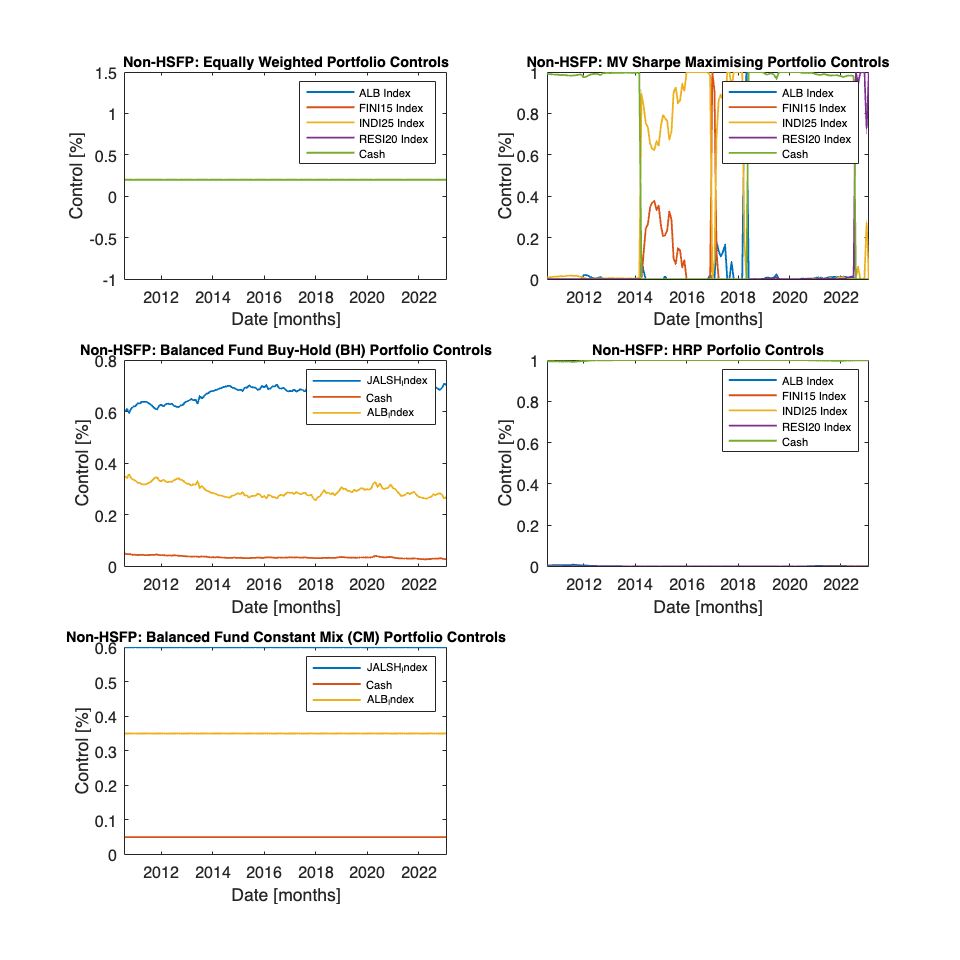

% Create fig
figure('OuterPosition', [100, 100, 600, 600]);
% plot grid 
numRows = 3;
numCols = 2;

% Colour palette: Hexadecimal Colour Codes
colours = [0.3010 0.7450 0.9330; % blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880]; % green

    % Create scatter plot of current_var and current_lag
      % Create scatter plot of current_var and current_lag
    subplot(numRows, numCols, 1);
    axis square;
    plot(BF_BH_TT.Time(Window:t,:),Overlap_tsEW_Wts, 'LineWidth', 1.2);
    title('Non-HSFP: Equally Weighted Portfolio Controls','FontSize', 9);
    xlabel('Date [months]');
    ylabel('Control [%]');
    legend(ASSETCL_PlotNames, "FontSize",7)


    subplot(numRows, numCols, 2);
    plot(BF_BH_TT.Time(Window:t,:),Overlap_tsSR_Wts,'LineWidth', 1.12);
    title('Non-HSFP: MV Sharpe Maximising Portfolio Controls','FontSize', 9);
    xlabel('Date [months]');
    ylabel('Control [%]');
    legend(ASSETCL_PlotNames, "FontSize",7)

    subplot(numRows, numCols, 3);
    plot(BF_BH_TT.Time(Window:t,:),Overlap_tsBH_Wts0,'LineWidth', 1.12);
    title('Non-HSFP: Balanced Fund Buy-Hold (BH) Portfolio Controls','FontSize', 9);
    xlabel('Date [months]');
    ylabel('Control [%]');
    legend(BF_BH_TT.Properties.VariableNames, "FontSize",7)
    

    subplot(numRows, numCols, 4);
    plot(BF_BH_TT.Time(Window:t,:),Overlap_tsHRP_Wts,'LineWidth', 1.2);
    title('Non-HSFP: HRP Porfolio Controls','FontSize', 9);
    xlabel('Date [months]');
    ylabel('Control [%]');
    legend(ASSETCL_PlotNames, "FontSize",7)

    subplot(numRows, numCols, 5);
    plot(BF_BH_TT.Time(Window:t,:),Overlap_tsCM_Wts,'LineWidth', 1.2);
    title('Non-HSFP: Balanced Fund Constant Mix (CM) Portfolio Controls','FontSize', 9);
    xlabel('Date [months]');
    ylabel('Control [%]');
    legend(BF_BH_TT.Properties.VariableNames, "FontSize",7)
%      subplot(numRows, numCols, 6);
%     plot(BF_BH_TT.Time(Window:t,:),Overlap_tsCM_Wts,'LineWidth', 1.2);
%     title('Non-HSFP: Balanced Fund Constant Mix (CM) Portfolio Controls','FontSize', 9);

%     xlabel('Date [months]');
%     ylabel('Control [%]');
%     legend(BALFUN_PlotNames(1:3), "FontSize",7, 'Location','eastoutside')
    
    
    % Make the x, y axes equal in length
 

% Export the fig as a PDF
% Export the fig as a PDF
UnAdj_RollW_Wt_Surfaces_Plot = gcf;
% hold off

exportName = 'UnAdj_RollW_Wt_Surfaces_Plot.pdf';
exportgraphics(UnAdj_RollW_Wt_Surfaces_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

### **3.4 Alternative Benchmarks:** ALSI & ALBI & Cash (JIBA3M)

Overlap_tsALSI_PRet = table2array(BF_BH_TT(Window:t, 'JALSH_Index'));
% 0 to start of series to match length of return series from backtest loop
Overlap_tsALSI_PRet(1, :) = 0;
Overlap_tsALBI_PRet = table2array(M_Ret_TT(Window:t, 'ALB_Index'));
Overlap_tsALBI_PRet(1, :) = 0;
Overlap_tsCash_PRet = table2array(M_Ret_TT(Window:t, 'Cash'));
Overlap_tsCash_PRet(1, :) = 0;
SR_Overall_ALSI = (mean(Overlap_tsALSI_PRet)-Rfr)/std(Overlap_tsALSI_PRet);
SR_Overall_ALBI = (mean(Overlap_tsALBI_PRet)-Rfr)/std(Overlap_tsALBI_PRet);
SR_Overall_Cash = (mean(Overlap_tsCash_PRet)-Rfr)/std(Overlap_tsCash_PRet);

### 3.5 Returns to Price Series

% % Get the number of columns in the timetable
% [m,n] = size(M_Ret_TT);
% M_Ret_array =  table2array(M_Ret_TT);
% % % Preallocate arrays for monthly returns and geometric return series
% GRet = zeros(m-1, n);
% GRet_TT = timetable('RowTimes', M_Ret_TT.Time(2:end));
% % 
% % Calculate monthly returns and geometric return series for each column
% for col = 1:n
%     
%     % Convert the monthly returns to decimal form
%     decimal_returns = M_Ret_array(2:end, col) + 1; 
%     
%     % Calculate the geometric return series for the current variable
%     GRet(:, col) = cumprod(decimal_returns) - 1;
% end


## Geometrically compounding returns for performance series

% Create a cell array to store the resulting vectors
result_cell_array = cell(1,8); % Preallocate for 8 variables (EW, SR, BH, HRP, CM, ALSI, ALBI, Cash)

% Define the list of variables and their corresponding names
variables = {
    'EW', 'SR', 'BH', 'HRP', 'CM', 'ALSI', 'ALBI', 'Cash'
};

% Loop through the variables, calculate the indices, and store them in the cell array
for i = 1:length(variables)
    % Calculate the decimal return and cumulative product
    decimal_ret = eval(['Overlap_ts' variables{i} '_PRet(1:end,:) + 1']);
    PIndx = cumprod(decimal_ret);
    
    % Store the results in the cell array
    result_cell_array{i} = PIndx;
end

% 
% decimal_EW_Ret = Overlap_tsEW_PRet(Window:end,:) +1;
% O_tsEW_PIndx = cumprod(decimal_EW_Ret);
% 
% % 
% decimal_SR_Ret = Overlap_tsSR_PRet(1:end,:) +1;
% O_tsSR_PIndx = cumprod(decimal_SR_Ret);
% 
% decimal_BH_Ret = Overlap_tsBH_PRet(1:end,:) +1;
% O_tsBH_PIndx = cumprod(decimal_BH_Ret);
% 
% decimal_HRP_Ret = Overlap_tsHRP_PRet(1:end,:) +1;
% O_tsHRP_PIndx = cumprod(decimal_HRP_Ret);
% 
% decimal_CM_Ret = Overlap_tsCM_PRet(1:end,:) +1;
% O_tsCM_PIndx = cumprod(decimal_CM_Ret);
% 
% decimal_ALSI_Ret = Overlap_tsALSI_PRet(1:end,:) +1;
% O_tsALSI_PIndx = cumprod(decimal_ALSI_Ret);
% 
% decimal_ALBI_Ret = Overlap_tsALBI_PRet(1:end,:) +1;
% O_tsALBI_PIndx = cumprod(decimal_ALBI_Ret);
% 
% decimal_Cash_Ret = Overlap_tsCash_PRet(1:end,:) +1;
% O_tsCash_PIndx = cumprod(decimal_Cash_Ret);

### 3.6 Portfolio Timetable object to plot

% 'EW', 'SR', 'BH', 'HRP', 'CM', 'ALSI', 'ALBI', 'Cash'
Rolling_portfolioSet = timetable(M_Ret_TT.Time(Window:t,:), ...
  result_cell_array{1},result_cell_array{2},result_cell_array{3}, result_cell_array{4}, result_cell_array{5}, ...
   'VariableNames',{['EW (CM)  (SR = ' num2str(round(SR_Overall_EW,2)) ')'],['MVSR max  (SR = ' num2str(round(SR_Overall_MVSR,2)) ')'],['BalFund (BH)   (SR = ' num2str(round(SR_Overall_BH,2)) ')'],['HRP   (SR = ' num2str(round(SR_Overall_HRP,2)) ')'],['BalFund (CM)    (SR = ' num2str(round(SR_Overall_CM,2)) ')']});
% Rolling_portfolioSet = Rolling_portfolioSet(Window:t,:);
Rolling_portfolioSet=[Rolling_portfolioSet timetable(M_Ret_TT.Time(Window:t,:),result_cell_array{6},result_cell_array{7},result_cell_array{8} ,'VariableNames',{['ALSI  (SR = ' num2str(round(SR_Overall_ALSI,2)) ')'],['ALBI  (SR = ' num2str(round(SR_Overall_ALBI,2)) ')'], 'Cash (JIBA3M)'})];
%  O_tsALSI_PIndx,O_tsALBI_PIndx 'ALSI','ALBI',

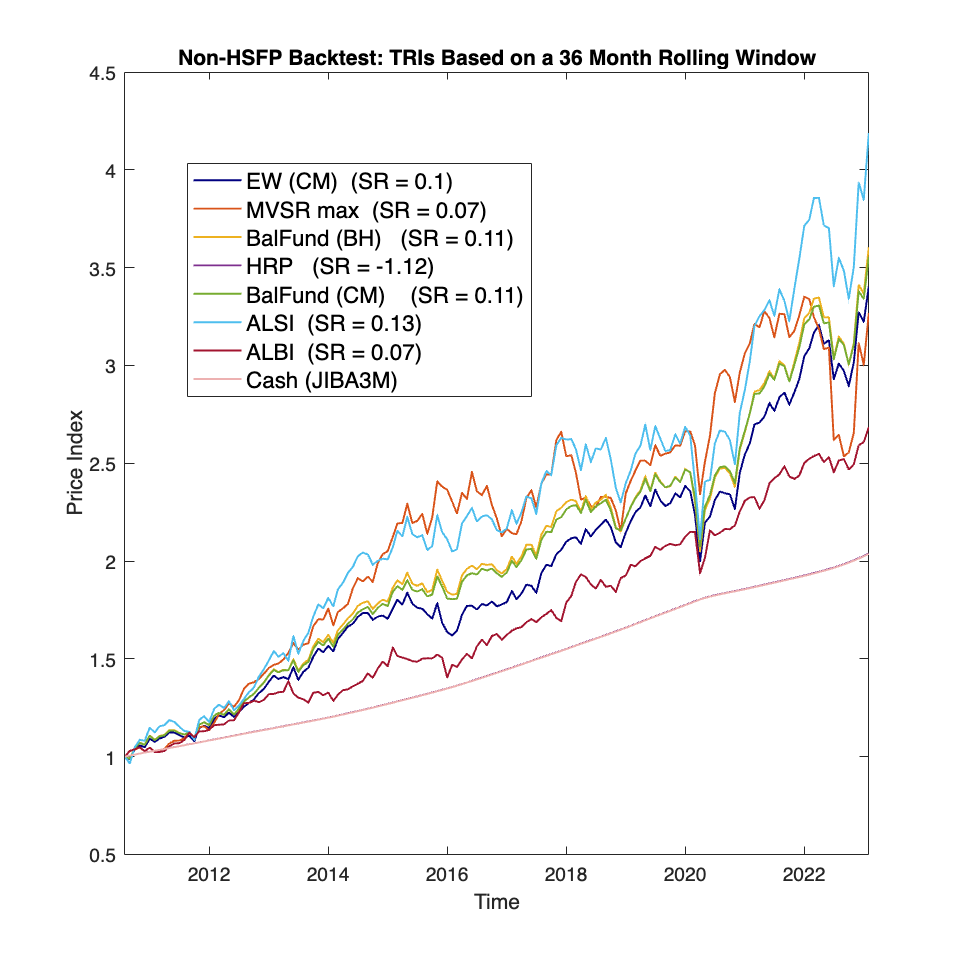

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(Rolling_portfolioSet.Time, Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
title(['Non-HSFP Backtest: TRIs Based on a ', num2str(Window), ' Month Rolling Window'], 'FontSize', 16);
legend(Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
UnAdj_36RollW_Output_Plot = gcf;
hold off;
 
legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])

exportName = 'UnAdj_36RollW_Output_Plot.pdf';
exportgraphics(UnAdj_36RollW_Output_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 3.7 Backtest summary Results

Put the following into a table to export

- Max Drawdown

- Turnover

- Annual Return

- Annual Volatility

- CVaR

- Sharpe Ratio

3.7.1 Max Drawdowns